# Leitor de arquivo no formato CRFS BIN.

Trata-se de leitor dos principais tipos de dados relacionados às versões 1, 2, 3, 4 e 5 de arquivo no formato CRFS BIN, gerado originalmente pela aplicação Logger, do RFeye.

Versão: **25/03/2022**

function specData = FileReader_CRFSBin_mat1(filename, ReadType, metaData)

    arguments
        filename char
        ReadType char   = 'SingleFile'
        metaData struct = []
    end
    
    global SpecInfo
    
    fileID = fopen(filename);
    if fileID == -1
        error('File not found.');
    end
    
    Format = fread(fileID, 1, 'int32', 32);
    switch Format
        case 21;   FileFormat = 'CRFS Bin v.2-3';
        case 22;   FileFormat = 'CRFS Bin v.4';
        case 23;   FileFormat = 'CRFS Bin v.5';
        otherwise; error('Appears not to be a CRFS Bin file.')
    end
    
    switch ReadType
        case {'MetaData', 'SingleFile'}
            SpecInfo = struct('Node',         '', 'ThreadID',   '', 'MetaData',   [], 'ObservationTime', '', 'Samples',   [],    ...
                              'Data',         {}, 'statsData',  [], 'FileFormat', '', 'TaskName',        '', 'Description', '',  ...
                              'RelatedFiles', {}, 'RelatedGPS', {}, 'gps',        [], 'Blocks',          []);

            Fcn_MetaDataReader(fileID, filename, FileFormat);

            if strcmp(ReadType, 'SingleFile')
                Fcn_SpecDataReader(fileID, filename)
            end
            
        case 'SpecData'
            SpecInfo = metaData(1).Data;
            Fcn_SpecDataReader(fileID, filename);
    end
    fclose(fileID);
    
    specData = SpecInfo;
    clear global SpecInfo
end

Leitura de **metadados**.

function Fcn_MetaDataReader(fileID, filename, FileFormat)

    global GPS

    DATATYPES    = [1:8, 21:22, 24, 40:42, 51, 60:69];
    messageTable = table('Size', [0, 2],                      ...
                         'VariableTypes', {'double', 'cell'}, ...
                         'VariableNames', {'ThreadID', 'Message'});
    Hostname     = '';
    Taskname     = '';
    GPS          = struct('Status', 0, 'Latitude', -1, 'Longitude', -1, 'Count', 0, 'Location', '', 'Matrix', []);

    fileInfo = dir(filename);
    fileSize = fileInfo.bytes;
    
    while ~feof(fileID)
        if fileSize-ftell(fileID) < 20
            break
        end

        ThreadID   = fread(fileID, 1, 'uint32');
        BytesBlock = fread(fileID, 1, 'uint32');
        DataType   = fread(fileID, 1,  'int32');

        try
            if ~ismember(DataType, DATATYPES)
                error(jsonencode(struct('type', 'DATATYPE', 'value', ftell(fileID)-12)))
            elseif fileSize-ftell(fileID) < BytesBlock+8
                error(jsonencode(struct('type', 'BLOCKSIZE', 'value', ftell(fileID)-12)))
            end
            
            if ~isempty(DataType)
                switch DataType
                    % Spectral data
                    case 67; Read_DataType67(fileID, 0, [ThreadID, BytesBlock, DataType]);    
                    case 68; Read_DataType68(fileID, 0, [ThreadID, BytesBlock, DataType]);
                    case 69; Read_DataType69(fileID, 0, [ThreadID, BytesBlock, DataType]);

                    case 63; Read_DataType63(fileID, 0, [ThreadID, BytesBlock, DataType]);
                    case 64; Read_DataType64(fileID, 0, [ThreadID, BytesBlock, DataType]);
                    case 65; Read_DataType65(fileID, 0, [ThreadID, BytesBlock, DataType]);
                    
                    case 60; Read_DataType60(fileID, 0, [ThreadID, BytesBlock, DataType]);
                    case 61; Read_DataType61(fileID, 0, [ThreadID, BytesBlock, DataType]);
                    case 62; Read_DataType62(fileID, 0, [ThreadID, BytesBlock, DataType]);
                    
                    case  4; Read_DataType04(fileID, 0, [ThreadID, BytesBlock, DataType]);
                    case  7; Read_DataType07(fileID, 0, [ThreadID, BytesBlock, DataType]);
                    case  8; Read_DataType08(fileID, 0, [ThreadID, BytesBlock, DataType]);

                    % GPS data
                    case {2, 40}
                        if DataType == 2; Read_DataType02(fileID, BytesBlock);
                        else;             Read_DataType40(fileID, BytesBlock);
                        end

                    % Thread info
                    case {3, 22, 24}
                        if    DataType == 24; Description = Read_DataType24(fileID, BytesBlock);
                        else;                 Description = Read_DataType22(fileID, BytesBlock);
                        end
                        messageTable(end+1, :) = {ThreadID, Description};
                        
                    % Free text
                    case {5, 41, 42}
                        if     DataType ==  5; Read_DataType05(fileID, BytesBlock);
                        elseif DataType == 41; Read_DataType41(fileID, BytesBlock);
                        else;                  Read_DataType42(fileID, BytesBlock);
                        end
                        
                    % Unit info
                    case {1, 21}
                        if DataType == 1; [Hostname, Taskname] = Read_DataType01(fileID, BytesBlock);
                        else;             [Hostname, Taskname] = Read_DataType21(fileID, BytesBlock);
                        end
                        
                    % Others
                    otherwise; Read_OthersTypes(fileID, BytesBlock, DataType);
                end
            end
        catch ME
            msg = '';
            try
                msg = jsondecode(ME.message);
            catch
            end

            if ~isempty(msg) && isfield(msg, 'value')
                fseek(fileID, msg.value, 'bof');
            end
            FindNextBlock(fileID)
        end
    end
    
    if GPS.Status
        GPS.Matrix    = GPS.Matrix / 1e+6;
        GPS.Count     = height(GPS.Matrix);
        GPS.Latitude  = mean(GPS.Matrix(:,1));
        GPS.Longitude = mean(GPS.Matrix(:,2));          
        
        GPS.Location  = FindCity(GPS);
    end

    Fcn_DataOrganization(fileID, fileInfo, filename, Hostname, FileFormat, Taskname, messageTable)

end

Leitura de informações de **níveis apenas dos dados de blocos espectrais (incluso ocupação)**.

Analisadas três opções de organização dos dados:

- Timetable. A mais bonita. A mais ineficiente. Leitura de arquivo de referência em 47 segundos.

- Cell array. DateStr e Matrix. A mais eficiente. Perde o datetimeruler no plot (e os filtros de timestamp). Necessário organizar como "yyyy/mm/dd HH:MM:SS" para possibilitar ordenação. Leitura de arquivo de referência em 5 segundos.

- Cell array. DateTime e Matrix. Leitura de arquivo de referência em 8 segundos.

function Fcn_SpecDataReader(fileID, filename)

    global SpecInfo
    
    for ii = 1:numel(SpecInfo)
        SpecInfo(ii).Data  = {repmat(datetime([0 0 0 0 0 0], 'Format', 'dd/MM/yyyy HH:mm:ss'), 1, SpecInfo(ii).Samples), ...
                              zeros(SpecInfo(ii).MetaData.DataPoints, SpecInfo(ii).Samples, 'single')};

        for jj = 1:SpecInfo(ii).Samples
            switch SpecInfo(ii).MetaData.DataType
                case 67; Read_DataType67(fileID, 1, [], ii, jj);
                case 68; Read_DataType68(fileID, 1, [], ii, jj);
                case 69; Read_DataType69(fileID, 1, [], ii, jj);

                case 63; Read_DataType63(fileID, 1, [], ii, jj);
                case 64; Read_DataType64(fileID, 1, [], ii, jj);
                case 65; Read_DataType65(fileID, 1, [], ii, jj);
                
                case 60; Read_DataType60(fileID, 1, [], ii, jj);
                case 61; Read_DataType61(fileID, 1, [], ii, jj);
                case 62; Read_DataType62(fileID, 1, [], ii, jj);
                
                case  4; Read_DataType04(fileID, 1, [], ii, jj);
                case  7; Read_DataType07(fileID, 1, [], ii, jj);
                case  8; Read_DataType08(fileID, 1, [], ii, jj);
            end
        end

        if ismember(SpecInfo(ii).MetaData.DataType, [4, 7])
            fileInfo = dir(filename);
            SpecInfo(ii).Data{1}(1:end) = linspace(datetime(fileInfo.date)-seconds(SpecInfo(ii).Samples-1), datetime(fileInfo.date), SpecInfo(ii).Samples);
        end
    end

end

# Funções auxiliares

**Organização da variável specData.**

function Fcn_DataOrganization(fileID, fileInfo, filename, Hostname, FileFormat, Taskname, messageTable)

    global SpecInfo
    global GPS

    messageTable(~ismember(messageTable{:,1}, [SpecInfo.ThreadID]), :) = [];
    [~, file, ext] = fileparts(filename);

    for ii = 1:numel(SpecInfo)
        SpecInfo(ii).Node       = Hostname;
        SpecInfo(ii).FileFormat = FileFormat;
        SpecInfo(ii).TaskName   = Taskname;
                
        %% String com alguns dos metadados p/ simplificar leitura no app.
        %% Unidade
        switch SpecInfo(ii).MetaData.LevelUnit
            case 0; SpecInfo(ii).MetaData.LevelUnit = 1; Unit = 'dBm';
            case 1; SpecInfo(ii).MetaData.LevelUnit = 3; Unit = 'dBµV/m';
        end
        
        %% Resolução
        if SpecInfo(ii).MetaData.Resolution == -1
            SpecInfo(ii).MetaData.Resolution = [];
        end
        
        Resolution = '';
        if ~isempty(SpecInfo(ii).MetaData.Resolution)
            Resolution = sprintf('%.3f kHz', SpecInfo(ii).MetaData.Resolution/1000);
        end
        
        %% Processamento do traço.
        traceMode = '';
        if ismember(SpecInfo(ii).MetaData.DataType, [8, 62, 65, 69])
            traceMode = 'OCC';
        else
            switch SpecInfo(ii).MetaData.TraceMode
                case 0; traceMode = 'Single Measurement';
                case 1; traceMode = 'Mean';
                case 2; traceMode = 'Peak';
                case 3; traceMode = 'Minimum';
            end
        end

        %% Detector
        Detector = '';
        
        %% Antena.
        antennaName = '';
        if ~isempty(SpecInfo(ii).MetaData.Antenna)
            switch SpecInfo(ii).MetaData.Antenna
                case 0; antennaName = 'CRFS RFeye (Auto)';
                case 1; antennaName = 'CRFS RFeye Port 1';
                case 2; antennaName = 'CRFS RFeye Port 2';
                case 3; antennaName = 'CRFS RFeye Port 3';
                case 4; antennaName = 'CRFS RFeye Port 4';
            end
        end
        SpecInfo(ii).MetaData = rmfield(SpecInfo(ii).MetaData, 'Antenna');
        
        SpecInfo(ii).MetaData.metaString = {Unit, Resolution, traceMode, Detector, antennaName};
        
        if ~isempty(messageTable)
            SpecInfo(ii).Description = Read_Description(messageTable, SpecInfo(ii).ThreadID, ii);
        end
        
        SpecInfo(ii).gps             = rmfield(GPS, {'Count', 'Matrix'});
        SpecInfo(ii).RelatedGPS      = {GPS};
        SpecInfo(ii).RelatedFiles    = {[file ext]}; 

        SpecInfo(ii).ObservationTime = Read_ObservationTime(fileID, fileInfo, ii);

        %% SampleTime (only OCC info - integration factor)
        if ~isempty(SpecInfo(ii).MetaData.SampleTime)
            SpecInfo(ii).MetaData.SampleTime = SpecInfo(ii).MetaData.SampleTime / SpecInfo(ii).Samples;
        end
    end

    if ~issorted([SpecInfo.ThreadID])
        [~, indSort] = sort([SpecInfo.ThreadID]);
        SpecInfo     = SpecInfo(indSort);
    end

end

**CheckSum**

function CheckSumAdd = Read_CheckSum(fileID, BytesBlock)
    
    fseek(fileID, -12, 'cof');
    
    auxCheckSum = fread(fileID, BytesBlock+12, 'uint8');
    CheckSumAdd = uint32(sum(auxCheckSum));
    
    fseek(fileID, -BytesBlock, 'cof');
    
end

**Data Block Trailer**

function Read_DataBlockTrailer(fileID, StartByte, CalculatedCheckSum, GERROR)

    EstimatedCheckSum = fread(fileID, 1, 'uint32');
    EstimatedEOF      = fread(fileID, [1, 4], '*char');
    
    if ~strcmp(EstimatedEOF, 'UUUU')
        error(jsonencode(struct('type', 'EOF', 'value', StartByte-12)))

    elseif EstimatedCheckSum ~= CalculatedCheckSum
        error(jsonencode(struct('type', 'CHECKSUM', 'value', StartByte-12)))
    
    elseif GERROR ~= -1
        error(jsonencode(struct('type', 'GERROR', 'value', StartByte-12)))
    end

end

**Find New Block**

function FindNextBlock(fileID)

    DATATYPES = [1:8, 21:22, 24, 40:42, 51, 60:69];

    Position = ftell(fileID);
    Flag     = 0;

    rawData  = fread(fileID, [1, Inf], 'uint8=>uint8');
    rawIndex = strfind(char(rawData), 'UUUU');
    if isempty(rawIndex)
        return
    end

    ii = 1;
    while ii <= numel(rawIndex)
        if ii == 1; ind1 = 1;
        else;       ind1 = rawIndex(ii-1)+4;
        end
        ind2     = rawIndex(ii)+3;
        rawArray = rawData(ind1:ind2);

        try
            jj = 0;
            while numel(rawArray) < 20
                jj = jj+1;
                
                ind2     = rawIndex(ii+jj)+3;
                rawArray = rawData(ind1:ind2);
            end

            BytesBlock = typecast(rawArray(5:8),  'uint32');
            DataType   = typecast(rawArray(9:12), 'uint32');

            if ~ismember(DataType, DATATYPES)
                error('DATATYPE')
            end

            tStart = tic;
            while numel(rawArray) < BytesBlock+20
                jj = jj+1;

                ind2     = rawIndex(ii+jj)+3;
                rawArray = rawData(ind1:ind2);

                if toc(tStart) > .1
                    error('BLOCKTIMEOUT')
                end
            end
    
            if numel(rawArray) ~= BytesBlock+20
                error('BLOCKSIZE')
            end
    
            EstimatedCheckSum  = typecast(rawArray(end-7:end-4), 'uint32');
            CalculatedCheckSum = uint32(sum(rawArray(1:end-8)));
    
            if EstimatedCheckSum ~= CalculatedCheckSum
                error('CHECKSUM')
            end

            Flag = 1;
            break
    
        catch ME
            switch ME.message
                case {'CHECKSUM', 'GERROR'}
                    ii = ii+jj+1;
                otherwise % 'DATATYPE', 'BLOCKTIMEOUT' and 'BLOCKSIZE'
                    ii = ii+1;
            end
        end
    end

    if Flag
        fseek(fileID, Position+ind1-1, 'bof');
    end

end

**Identificação de fluxo.**

function Read_auxDataType(fileID, Bin, ThreadID, BytesBlock, Description)

    global SpecInfo

    ID  = numel(SpecInfo)+1;
    ind = find([SpecInfo.ThreadID] == ThreadID);

    if ~isempty(ind)
        for ii = ind
            if isequal(rmfield(Bin, 'SampleTime'), rmfield(SpecInfo(ii).MetaData, 'SampleTime'))
                ID = ii;
                break
            end
        end
    end
    
    if ID > numel(SpecInfo)
        SpecInfo(ID).ThreadID = ThreadID;
        SpecInfo(ID).MetaData = Bin;
        SpecInfo(ID).Samples  = 1;        
        SpecInfo(ID).Blocks   = zeros(1, 65536);
        
        if ~isempty(Description)
            SpecInfo(ID).Description = Description;
        end
        
    else
        if SpecInfo(ID).Samples == 65536
            return
        end
        
        SpecInfo(ID).Samples = SpecInfo(ID).Samples + 1;
        
        if ~isempty(Bin.SampleTime)
            SpecInfo(ID).MetaData.SampleTime = SpecInfo(ID).MetaData.SampleTime + Bin.SampleTime;
        end
    end
    SpecInfo(ID).Blocks(SpecInfo(ID).Samples) = ftell(fileID) - (BytesBlock+8);

end

**Timestamp**

function TimeStamp = Read_TimeStamp(fileID, DataType)

    Date_Day     = fread(fileID, 1);
    Date_Month   = fread(fileID, 1);
    Date_Year    = fread(fileID, 1, 'uint8', 1) + 2000;
    Time_Hours   = fread(fileID, 1);
    Time_Minutes = fread(fileID, 1);
    Time_Seconds = fread(fileID, 1, 'uint8', 1);

    if ismember(DataType, [60:65, 67:69])
        Time_nanoSec = fread(fileID, 1, 'uint32');
    else
        Time_nanoSec = 0;
        fseek(fileID, 4, 'cof');
    end
    
    TimeStamp    = datetime([Date_Year, Date_Month, Date_Day, Time_Hours, Time_Minutes, (Time_Seconds+Time_nanoSec/1e+9)]);

end

**Observation time**

function ObservationTime = Read_ObservationTime(fileID, fileInfo, ind)

    global SpecInfo
    
    SpecInfo(ind).Blocks(SpecInfo(ind).Blocks == 0) = [];

    if ismember(SpecInfo(ind).MetaData.DataType, [4, 7])
        StartTime = datestr(fileInfo.date, 'dd/mm/yyyy HH:MM:SS');
        StopTime  = datestr(datetime(fileInfo.date) + seconds(SpecInfo(ind).Samples-1), 'dd/mm/yyyy HH:MM:SS');
    
    elseif SpecInfo(ind).MetaData.DataType == 8
        fseek(fileID, SpecInfo(ind).Blocks(1)+12, 'bof');
        StartTime = datestr(Read_TimeStamp(fileID, 8), 'dd/mm/yyyy HH:MM:SS');
    
        fseek(fileID, SpecInfo(ind).Blocks(end)+12, 'bof');
        StopTime  = datestr(Read_TimeStamp(fileID, 8), 'dd/mm/yyyy HH:MM:SS');

    else
        fseek(fileID, SpecInfo(ind).Blocks(1), 'bof');
        StartTime = datestr(Read_TimeStamp(fileID, SpecInfo(ind).MetaData.DataType), 'dd/mm/yyyy HH:MM:SS');
    
        fseek(fileID, SpecInfo(ind).Blocks(end), 'bof');
        StopTime  = datestr(Read_TimeStamp(fileID, SpecInfo(ind).MetaData.DataType), 'dd/mm/yyyy HH:MM:SS');
    end

    ObservationTime = sprintf('%s - %s', StartTime, StopTime);
    
end

**Description (CRFS Bin v. 3-4)**

function Description = Read_Description(messageTable, ThreadID, ii)

    global SpecInfo

    Description = '';
    if isequal(messageTable.ThreadID', [SpecInfo.ThreadID])
        Description = messageTable.Message{ii};

    else
        ind = find(messageTable.ThreadID == ThreadID);

        if ~isempty(ind)
            if numel(ind) == 1
                Description = messageTable.Message{ind};
            else
                Description = jsonencode(messageTable(ind,:));
            end
        end
    end

end

# Tipos de dados.

A seguir é apresentada tabela com os tipos de dados gerados pelo RFEye Logger. A versão dos tipos de dados, diga-se, é indicada no início do *script* carregado no Logger, na forma "file_version = 5". E essa informação é recuperada logo no início do arquivo binário, nos campos "FH_Format" (número) e "FH_sFormat" (string), da seguinte forma: FH_Format = 21 (file_version = 3), 22 (file_version = 4) e 23 (file_version = 5).

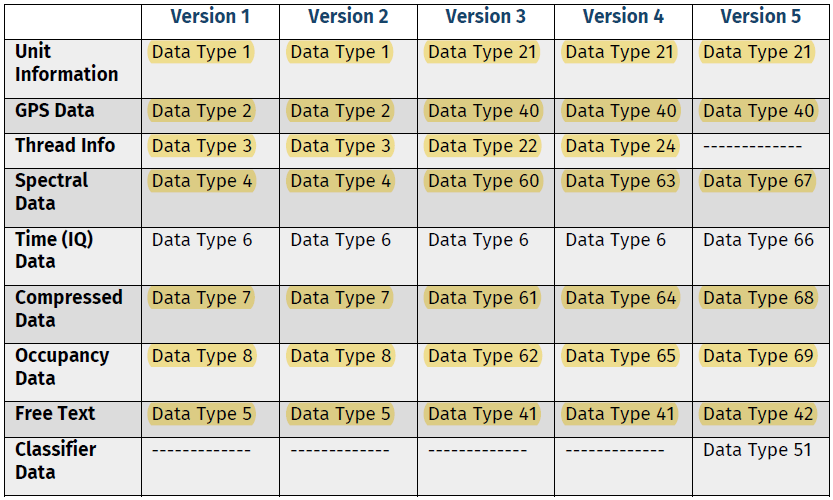

Em destaque os tipos de dados já implantados. 

## **Unit Info: [1, 21]**

DataType 1

function [Hostname, Taskname] = Read_DataType01(fileID, BytesBlock)
    
    StartByte = ftell(fileID);

    try
        CheckSumAdd   = Read_CheckSum(fileID, BytesBlock);
    
        Hostname      = deblank(fread(fileID, [1, 16], '*char'));
        Hostname(1:2) = upper(Hostname(1:2));
        Hostname      = erase(Hostname, '_');
        
        Text1Length   = fread(fileID, 1, 'uint32');
        fseek(fileID, Text1Length, 'cof');
        
        Taskname      = 'Unknown info';
        fseek(fileID, 4, 'cof');
    catch
        error(jsonencode(struct('type', 'TEXTLENGTH', 'value', StartByte-12)))
    end

    Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, []);
    
end

DataType 21

function [Hostname, Taskname] = Read_DataType21(fileID, BytesBlock)
    
    StartByte = ftell(fileID);

    try
        CheckSumAdd   = Read_CheckSum(fileID, BytesBlock);
    
        Hostname      = deblank(fread(fileID, [1, 16], '*char'));
        Hostname(1:2) = upper(Hostname(1:2));
        Hostname      = erase(Hostname, '_');
        
        Text1Length   = fread(fileID, 1, 'uint32');
        fseek(fileID, Text1Length, 'cof');
        
        Text2Length   = fread(fileID, 1, 'uint32');
        Taskname      = deblank(fread(fileID, [1, Text2Length], '*char'));    % method = "ScriptRFeye2020_v.1"
        Taskname      = erase(Taskname, '_');
    
        fseek(fileID, 4, 'cof');
    catch
        error(jsonencode(struct('type', 'TEXTLENGTH', 'value', StartByte-12)))
    end
    
    Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, []);
    
end

## **GPS Data: [2, 40]**

DataType 2

function Read_DataType02(fileID, BytesBlock)

    global GPS

    StartByte     = ftell(fileID);
    CheckSumAdd   = Read_CheckSum(fileID, BytesBlock);
    
    fseek(fileID, 10, 'cof');
    Status    = fread(fileID, 1,  'uint16', 2);
    Latitude  = fread(fileID, 1,  'int32');
    Longitude = fread(fileID, 1,  'int32', 10);

    if Status
        GPS.Status          = 1;
        GPS.Matrix(end+1,:) = [Latitude, Longitude];
    end

    Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, []);
    
end

DataType 40

A leitura se restringe àquilo que compõe specData, não englobando, na presente data, a informação dos campos Timestamp, Satellites, Heading, Speed e Altitude. A seguir são apresentados trechos do código, sendo a parte comentada exatamente àquela não está sendo lida.

function Read_DataType40(fileID, BytesBlock)

    global GPS

    StartByte     = ftell(fileID);
    CheckSumAdd   = Read_CheckSum(fileID, BytesBlock);
    
    fseek(fileID, 20, 'cof');              
    Status    = fread(fileID, 1, 'uint8', 3);
    Latitude  = fread(fileID, 1, 'int32');
    Longitude = fread(fileID, 1, 'int32', 8);

    if Status
        GPS.Status          = 1;
        GPS.Matrix(end+1,:) = [Latitude, Longitude];
    end

    Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, []);
    
end

## **Thread Info: [3, 22, 24]**

DataTypes 3/22

function Description = Read_DataType22(fileID, BytesBlock)
    
    StartByte = ftell(fileID);

    try
        CheckSumAdd = Read_CheckSum(fileID, BytesBlock);
        
        Text1Length = fread(fileID, 1, 'uint32');
        Description = deblank(fread(fileID, [1, Text1Length], '*char'));
    catch
        error(jsonencode(struct('type', 'TEXTLENGTH', 'value', StartByte-12)))
    end

    Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, []);
    
end

DataType 24

function Description = Read_DataType24(fileID, BytesBlock)

    StartByte   = ftell(fileID);
    CheckSumAdd = Read_CheckSum(fileID, BytesBlock);
    
    fseek(fileID, 4, 'cof');
    Text1Length = fread(fileID, 1, 'uint32');
    Description = deblank(fread(fileID, [1, Text1Length], '*char'));    % {'trace mode: Clear/Write ', 'trace mode: Clear/Write, threshold: -85 dBm ', 'trace mode: MaxHold, count = 10 '}
    
    Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, []);
    
end

## **Free Text: [5, 41, 42]**

DataType 5

function Read_DataType05(fileID, BytesBlock)
    
    StartByte = ftell(fileID);

    try
        CheckSumAdd = Read_CheckSum(fileID, BytesBlock);
        
        TextLength  = fread(fileID, 1, 'uint32');
        fseek(fileID, TextLength, 'cof');
    catch
        error(jsonencode(struct('type', 'TEXTLENGTH', 'value', StartByte-12)))
    end
    
    Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, []);
    
end

DataType 41

A leitura se restringe àquilo que compõe specData, não englobando, na presente data, a informação do campo Timestamp, Identifier ou FreeText. A seguir é apresentado trecho do código, sendo a parte comentada exatamente àquela não está sendo lida.

function Read_DataType41(fileID, BytesBlock)
        
    StartByte = ftell(fileID);

    try
        CheckSumAdd = Read_CheckSum(fileID, BytesBlock);
        
        fseek(fileID, 44, 'cof');
        TextLength = fread(fileID, 1, 'uint32');
        fseek(fileID, TextLength, 'cof');
        
        RefByte    = ftell(fileID) - StartByte;
        if RefByte < BytesBlock
            fseek(fileID, BytesBlock-RefByte, 'cof');
        end
    catch
        error(jsonencode(struct('type', 'TEXTLENGTH', 'value', StartByte-12)))
    end
    
    Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, []);
    
end

DataType 42

A leitura se restringe àquilo que compõe specData, não englobando, na presente data, a informação do campo Timestamp. A seguir é apresentado trecho do código, sendo a parte comentada exatamente àquela não está sendo lida.

function Read_DataType42(fileID, BytesBlock)
    
    StartByte = ftell(fileID);

    try
        CheckSumAdd = Read_CheckSum(fileID, BytesBlock);
        
        fseek(fileID, 52, 'cof');
        TextLength  = fread(fileID, 1, 'uint32');
        fseek(fileID, TextLength, 'cof');
        
        RefByte     = ftell(fileID) - StartByte;
        if RefByte < BytesBlock
            fseek(fileID, BytesBlock-RefByte, 'cof');
        end
    catch
        error(jsonencode(struct('type', 'TEXTLENGTH', 'value', StartByte-12)))
    end
    
    Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, []);
    
end

## **Spectral Data: [4, 7, 8, 60, 61, 62, 63, 64, 65, 67, 68, 69]**

DataType 4

function Read_DataType04(fileID, Flag, BlockHeader, ii, jj)

    global SpecInfo
    
    if ~Flag
        StartByte   = ftell(fileID);
        CheckSumAdd = Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',   0, 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
        
        Bin.FreqStart  = fread(fileID, 1, 'uint16')    * 1e+6;
        Bin.FreqStop   = fread(fileID, 1, 'uint16', 1) * 1e+6;
        Bin.Antenna    = fread(fileID, 1, 'uint8');
        Bin.TraceMode  = fread(fileID, 1, 'uint8'); 

        GERROR         = -1;
        NPAD           = fread(fileID, 1);
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, Bin.DataPoints+NPAD, 'cof');

        Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, GERROR);
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')
    
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj)+4, 'bof');
        
        OFFSET    = fread(fileID, 1, 'int8', 7);
        TraceData = fread(fileID, [SpecInfo(ii).MetaData.DataPoints, 1], 'uint8');
        
        SpecInfo(ii).Data{2}(:,jj) = -single(TraceData)./2 + OFFSET;
    end

end

DataType 7 (Compressed)

function Read_DataType07(fileID, Flag, BlockHeader, ii, jj)

    global SpecInfo
    
    if ~Flag
        StartByte   = ftell(fileID);
        CheckSumAdd = Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',   0, 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
        
        Bin.FreqStart  = fread(fileID, 1, 'uint32')    * 1e+6;
        Bin.FreqStop   = fread(fileID, 1, 'uint32', 4) * 1e+6;
        Bin.Threshold  = fread(fileID, 1,  'int32');
        Bin.Antenna    = fread(fileID, 1, 'uint32');
        Bin.TraceMode  = fread(fileID, 1, 'uint32', 4);

        GERROR         = -1;
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        NPAD           = fread(fileID, 1, 'uint32');
        NCDATA         = fread(fileID, 1, 'uint32');
        
        fseek(fileID, NCDATA+NPAD, 'cof');

        Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, GERROR);
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')
    
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj)+8, 'bof');
        
        OFFSET    = fread(fileID, 1,  'int32') - 127.5;
        THRESH    = fread(fileID, 1,  'int32', 20) - 1;
        NCDATA    = fread(fileID, 1, 'uint32');        

        Read_CompressedSpecData(fileID, NCDATA, THRESH, OFFSET, ii, jj);
    end

end

DataType 8 (OCC)

function Read_DataType08(fileID, Flag, BlockHeader, ii, jj)

    global SpecInfo

    if ~Flag
        StartByte   = ftell(fileID);
        CheckSumAdd = Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',   0, 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
        
        Bin.FreqStart  = fread(fileID, 1, 'uint32') * 1e+6;
        Bin.FreqStop   = fread(fileID, 1, 'uint32') * 1e+6;
        Bin.Threshold  = fread(fileID, 1,  'int32', 8);
        Bin.SampleTime = fread(fileID, 1, 'uint32');
        Bin.Antenna    = fread(fileID, 1, 'uint32', 4);

        GERROR         = -1;
        NPAD           = fread(fileID, 1, 'uint32');
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, Bin.DataPoints+NPAD, 'cof');

        Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, GERROR);
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')

    else
        fseek(fileID, SpecInfo(ii).Blocks(jj)+12, 'bof');
                
        TimeStamp = Read_TimeStamp(fileID, SpecInfo(ii).MetaData.DataType);
        fseek(fileID, 16, 'cof');

        TraceData = fread(fileID, [SpecInfo(ii).MetaData.DataPoints, 1], 'uint8');
        
        SpecInfo(ii).Data{1}(jj)   = TimeStamp;
        SpecInfo(ii).Data{2}(:,jj) = single(TraceData)./2;
    end

end

DataType 60

function Read_DataType60(fileID, Flag, BlockHeader, ii, jj)

    global SpecInfo
    
    if ~Flag
        StartByte   = ftell(fileID);
        CheckSumAdd = Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',   0, 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
      
        fseek(fileID, 12, 'cof');
        
        auxF0 = fread(fileID, 1, 'uint32');
        auxF1 = fread(fileID, 1, 'uint32');
        expF0 = fread(fileID, 1, 'int8');
        
        Bin.FreqStart  = auxF0 .* 10^expF0;
        Bin.FreqStop   = auxF1 .* 10^expF0;
        Bin.Antenna    = fread(fileID, 1, 'uint8');
        GERROR         = fread(fileID, 1,  'int8', 3);
        Bin.TraceMode  = fread(fileID, 1, 'uint8', 2); 
        NPAD           = fread(fileID, 1);
        NTUN           = fread(fileID, 1, 'uint16');
        NAGC           = fread(fileID, 1, 'uint16', 2);
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+Bin.DataPoints+NPAD, 'cof');

        Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, GERROR);
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')
    
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        TimeStamp = Read_TimeStamp(fileID, SpecInfo(ii).MetaData.DataType);
        fseek(fileID, 16, 'cof');
        
        OFFSET    = fread(fileID, 1, 'int8', 1) - 127.5;
        NTUN      = fread(fileID, 1, 'uint16');
        NAGC      = fread(fileID, 1, 'uint16');
        
        fseek(fileID, 4*NTUN+NAGC+6, 'cof');
        TraceData = fread(fileID, [SpecInfo(ii).MetaData.DataPoints, 1], 'uint8');
        
        SpecInfo(ii).Data{1}(jj)   = TimeStamp;
        SpecInfo(ii).Data{2}(:,jj) = single(TraceData)./2 + OFFSET;
    end
    
end

DataType 61 (Compressed)

function Read_DataType61(fileID, Flag, BlockHeader, ii, jj)
    
    global SpecInfo
    
    if ~Flag
        StartByte   = ftell(fileID);
        CheckSumAdd = Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',   0, 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
      
        fseek(fileID, 12, 'cof');
        
        auxF0 = fread(fileID, 1, 'uint32');
        auxF1 = fread(fileID, 1, 'uint32');
        expF0 = fread(fileID, 1, 'int8');
        
        Bin.FreqStart  = auxF0 .* 10^expF0;
        Bin.FreqStop   = auxF1 .* 10^expF0;
        Bin.Antenna    = fread(fileID, 1, 'uint8');
        GERROR         = fread(fileID, 1,  'int8', 3);
        Bin.TraceMode  = fread(fileID, 1, 'uint8', 2); 
        NPAD           = fread(fileID, 1);
        NTUN           = fread(fileID, 1, 'uint16');
        NAGC           = fread(fileID, 1, 'uint16', 2);
        NCDATA         = fread(fileID, 1, 'uint32');
        Bin.Threshold  = fread(fileID, 1, 'int32');
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+NCDATA+NPAD, 'cof');

        Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, GERROR);
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')
    
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');

        TimeStamp = Read_TimeStamp(fileID, SpecInfo(ii).MetaData.DataType);
        fseek(fileID, 16, 'cof');
        
        OFFSET    = fread(fileID, 1, 'int8', 1) - 127.5;
        NTUN      = fread(fileID, 1, 'uint16');
        NAGC      = fread(fileID, 1, 'uint16', 2);
        NCDATA    = fread(fileID, 1, 'uint32');
        THRESH    = fread(fileID, 1, 'int32') - 1;
        
        fseek(fileID, 4*NTUN+NAGC+4, 'cof');
        
        SpecInfo(ii).Data{1}(jj)   = TimeStamp;
        Read_CompressedSpecData(fileID, NCDATA, THRESH, OFFSET, ii, jj);
    end
    
end

DataType 62 (OCC)

function Read_DataType62(fileID, Flag, BlockHeader, ii, jj)
    
    global SpecInfo
    
    if ~Flag
        StartByte   = ftell(fileID);
        CheckSumAdd = Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',   0, 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
      
        fseek(fileID, 12, 'cof');
        
        auxF0 = fread(fileID, 1, 'uint32');
        auxF1 = fread(fileID, 1, 'uint32');
        expF0 = fread(fileID, 1, 'int8');
        
        Bin.FreqStart  = auxF0 .* 10^expF0;
        Bin.FreqStop   = auxF1 .* 10^expF0;
        Bin.Antenna    = fread(fileID, 1, 'uint8');
        GERROR         = fread(fileID, 1,  'int8',  3);
        Bin.Threshold  = fread(fileID, 1,  'int16', 4);
        Bin.SampleTime = fread(fileID, 1, 'uint32');
        NPAD           = fread(fileID, 1, 'uint8', 3);
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, Bin.DataPoints+NPAD, 'cof');

        Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, GERROR);
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')
        
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        TimeStamp = Read_TimeStamp(fileID, SpecInfo(ii).MetaData.DataType);
        fseek(fileID, 32, 'cof');
    
        TraceData = fread(fileID, [SpecInfo(ii).MetaData.DataPoints, 1], 'uint8');
        
        SpecInfo(ii).Data{1}(jj)   = TimeStamp;
        SpecInfo(ii).Data{2}(:,jj) = single(TraceData)./2;
    end
    
end

DataType 63

function Read_DataType63(fileID, Flag, BlockHeader, ii, jj)
    
    global SpecInfo

    if ~Flag
        StartByte   = ftell(fileID);
        CheckSumAdd = Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',  [], 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
      
        fseek(fileID, 12, 'cof');
        
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32');
        Bin.FreqStart  = (IntegerPart + DecimalPart ./ 1e+9) * 1e+6;
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32', 12);
        Bin.FreqStop   = (IntegerPart + DecimalPart ./ 1e+9) * 1e+6;
        Bin.Antenna    = fread(fileID, 1);
        Bin.TraceMode  = fread(fileID, 1);
        Bin.LevelUnit  = fread(fileID, 1, 'uint8', 1);
        GERROR         = fread(fileID, 1,  'int8', 2);
        NTUN           = fread(fileID, 1, 'uint16');
        NAGC           = fread(fileID, 1, 'uint16');
        NPAD           = fread(fileID, 1);
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+Bin.DataPoints+NPAD, 'cof');

        Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, GERROR);
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')

    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        TimeStamp = Read_TimeStamp(fileID, SpecInfo(ii).MetaData.DataType);
        fseek(fileID, 27, 'cof');
        
        OFFSET    = fread(fileID, 1, 'int8', 3) - 127.5;
        NTUN      = fread(fileID, 1, 'uint16');
        NAGC      = fread(fileID, 1, 'uint16');
        
        fseek(fileID, 4*NTUN+NAGC+5, 'cof');
        TraceData = fread(fileID, [SpecInfo(ii).MetaData.DataPoints, 1], 'uint8');

        SpecInfo(ii).Data{1}(jj)   = TimeStamp;
        SpecInfo(ii).Data{2}(:,jj) = single(TraceData)./2 + OFFSET;
    end
    
end

DataType 64 (Compressed)

function Read_DataType64(fileID, Flag, BlockHeader, ii, jj)
    
    global SpecInfo
    
    if ~Flag
        StartByte   = ftell(fileID);
        CheckSumAdd = Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',  [], 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
      
        fseek(fileID, 12, 'cof');
        
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32');
        Bin.FreqStart  = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32', 12);
        Bin.FreqStop   = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        Bin.Antenna    = fread(fileID, 1);
        Bin.TraceMode  = fread(fileID, 1);
        Bin.LevelUnit  = fread(fileID, 1, 'uint8', 1);
        GERROR         = fread(fileID, 1,  'int8', 2);
        NTUN           = fread(fileID, 1, 'uint16');
        NAGC           = fread(fileID, 1, 'uint16');
        NPAD           = fread(fileID, 1, 'uint8');
        NCDATA         = fread(fileID, 1, 'uint32');
        Bin.Threshold  = fread(fileID, 1, 'int32');
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, 4*NTUN+NAGC+NCDATA+NPAD, 'cof');

        Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, GERROR);
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')
        
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        TimeStamp = Read_TimeStamp(fileID, SpecInfo(ii).MetaData.DataType);
        fseek(fileID, 27, 'cof');
        
        OFFSET    = fread(fileID, 1, 'int8', 3) - 127.5;
        NTUN      = fread(fileID, 1, 'uint16');
        NAGC      = fread(fileID, 1, 'uint16', 1);
        NCDATA    = fread(fileID, 1, 'uint32');
        THRESH    = fread(fileID, 1, 'int32') - 1;
        
        fseek(fileID, 4*NTUN+NAGC+4, 'cof');
        
        SpecInfo(ii).Data{1}(jj)   = TimeStamp;
        Read_CompressedSpecData(fileID, NCDATA, THRESH, OFFSET, ii, jj);
    end
    
end

DataType 65 (OCC)

function Read_DataType65(fileID, Flag, BlockHeader, ii, jj)

    global SpecInfo
    
    if ~Flag
        StartByte   = ftell(fileID);
        CheckSumAdd = Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',  [], 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
      
        fseek(fileID, 12, 'cof');
        
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32');
        Bin.FreqStart  = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        IntegerPart    = fread(fileID, 1, 'uint16');
        DecimalPart    = fread(fileID, 1, 'int32', 8);
        Bin.FreqStop   = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
        Bin.Antenna    = fread(fileID, 1, 'uint8', 1);
        Bin.LevelUnit  = fread(fileID, 1, 'uint16');
        GERROR         = fread(fileID, 1,  'int8', 2);
        NPAD           = fread(fileID, 1);     
        Bin.Threshold  = fread(fileID, 1,  'int16');
        Bin.SampleTime = fread(fileID, 1, 'uint16');
        Bin.DataPoints = fread(fileID, 1, 'uint32');
        
        fseek(fileID, Bin.DataPoints+NPAD, 'cof');
        
        Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, GERROR);        
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), '')
        
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        TimeStamp = Read_TimeStamp(fileID, SpecInfo(ii).MetaData.DataType);
        fseek(fileID, 36, 'cof');
        
        TraceData = fread(fileID, [SpecInfo(ii).MetaData.DataPoints, 1], 'uint8');
        
        SpecInfo(ii).Data{1}(jj)   = TimeStamp;
        SpecInfo(ii).Data{2}(:,jj) = single(TraceData)./2;
    end
    
end

DataType 67

function Read_DataType67(fileID, Flag, BlockHeader, ii, jj)
    
    global SpecInfo
    
    if ~Flag
        StartByte   = ftell(fileID);
        CheckSumAdd = Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',  [], 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);
      
        fseek(fileID, 20, 'cof');
        TextLength = fread(fileID, 1, 'uint32');

        try
            Description    = deblank(fread(fileID, [1, TextLength], '*char'));
            IntegerPart    = fread(fileID, 1, 'uint16');
            DecimalPart    = fread(fileID, 1, 'int32');
            Bin.FreqStart  = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
            IntegerPart    = fread(fileID, 1, 'uint16');
            DecimalPart    = fread(fileID, 1, 'int32');
            Bin.FreqStop   = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
            
            Bin.Resolution = fread(fileID, 1,  'int32', 12);
            if Bin.Resolution == -1
                Bin.Resolution = [];                                        % Decodificação relacionada ao CRFS Bin gerado no appAnálise
            end
            
            Bin.Antenna    = fread(fileID, 1);
            Bin.TraceMode  = fread(fileID, 1);
            Bin.LevelUnit  = fread(fileID, 1, 'uint8', 1);
            GERROR         = fread(fileID, 1,  'int8', 2);
            
            NTUN           = fread(fileID, 1, 'uint16');
            NAGC           = fread(fileID, 1, 'uint16');
            NPAD           = fread(fileID, 1);
            Bin.DataPoints = fread(fileID, 1, 'uint32');
            
            fseek(fileID, 4*NTUN+NAGC+Bin.DataPoints+NPAD, 'cof');
        catch
            error(jsonencode(struct('type', 'TEXTLENGTH', 'value', StartByte-12)))
        end
        
        Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, GERROR);
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), Description)
        
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        TimeStamp  = Read_TimeStamp(fileID, SpecInfo(ii).MetaData.DataType);
        fseek(fileID, 8, 'cof');

        TextLength = fread(fileID, 1, 'uint32');
        fseek(fileID, TextLength+31, 'cof');
        
        OFFSET     = fread(fileID, 1, 'int8', 3) - 127.5;
        NTUN       = fread(fileID, 1, 'uint16');
        NAGC       = fread(fileID, 1, 'uint16');
        
        fseek(fileID, 4*NTUN+NAGC+5, 'cof');
        TraceData  = fread(fileID, [SpecInfo(ii).MetaData.DataPoints, 1], 'uint8');
        
        SpecInfo(ii).Data{1}(jj)   = TimeStamp;
        SpecInfo(ii).Data{2}(:,jj) = single(TraceData)./2 + OFFSET;
    end
    
end

DataType 68 (Compressed)

function Read_DataType68(fileID, Flag, BlockHeader, ii, jj)
    
    global SpecInfo
    
    if ~Flag
        StartByte   = ftell(fileID);
        CheckSumAdd = Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',  [], 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);

        fseek(fileID, 20, 'cof');
        TextLength = fread(fileID, 1, 'uint32');

        try
            Description    = deblank(fread(fileID, [1, TextLength], '*char'));
            IntegerPart    = fread(fileID, 1, 'uint16');
            DecimalPart    = fread(fileID, 1, 'int32');
            Bin.FreqStart  = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
            IntegerPart    = fread(fileID, 1, 'uint16');
            DecimalPart    = fread(fileID, 1, 'int32');
            Bin.FreqStop   = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
            Bin.Resolution = fread(fileID, 1, 'uint32', 12);
            Bin.Antenna    = fread(fileID, 1);
            Bin.TraceMode  = fread(fileID, 1);
            Bin.LevelUnit  = fread(fileID, 1, 'uint8', 1);
            GERROR         = fread(fileID, 1,  'int8', 2);
            NTUN           = fread(fileID, 1, 'uint16');
            NAGC           = fread(fileID, 1, 'uint16');
            NPAD           = fread(fileID, 1);
            NCDATA         = fread(fileID, 1, 'uint32');
            Bin.Threshold  = fread(fileID, 1, 'int32');
            Bin.DataPoints = fread(fileID, 1, 'uint32');
            
            fseek(fileID, 4*NTUN+NAGC+NCDATA+NPAD, 'cof');
        catch
            error(jsonencode(struct('type', 'TEXTLENGTH', 'value', StartByte-12)))
        end
        
        Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, GERROR);
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), Description)
        
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');
        
        TimeStamp  = Read_TimeStamp(fileID, SpecInfo(ii).MetaData.DataType);
        fseek(fileID, 8, 'cof');

        TextLength = fread(fileID, 1, 'uint32');
        fseek(fileID, TextLength+31, 'cof');
        
        OFFSET     = fread(fileID, 1, 'int8', 3) - 127.5;
        NTUN       = fread(fileID, 1, 'uint16');
        NAGC       = fread(fileID, 1, 'uint16', 1);
        NCDATA     = fread(fileID, 1, 'uint32');
        THRESH     = fread(fileID, 1, 'int32') - 1;
        
        fseek(fileID, 4+4*NTUN+NAGC, 'cof');
%         fseek(fileID, 4, 'cof');
%         TunningArray   = fread(fileID, [1, 4*NTUN]);
%         AGCValuesArray = fread(fileID, [1, NAGC]);
        
        SpecInfo(ii).Data{1}(jj)   = TimeStamp;
        Read_CompressedSpecData(fileID, NCDATA, THRESH, OFFSET, ii, jj);
        
    end
    
end

DataType 69 (OCC)

function Read_DataType69(fileID, Flag, BlockHeader, ii, jj)
    
    global SpecInfo
    
    if ~Flag
        StartByte   = ftell(fileID);
        CheckSumAdd = Read_CheckSum(fileID, BlockHeader(2));
        
        Bin = struct('DataType', BlockHeader(3),         'ThreadID', BlockHeader(1),         ...
                     'FreqStart',  [], 'FreqStop',   [], 'LevelUnit',  [], 'DataPoints', [], ...
                     'Resolution', [], 'SampleTime', [], 'Threshold',  [], 'TraceMode',  [], ...
                     'Detector',   [], 'Antenna',    []);

        fseek(fileID, 20, 'cof');      
        TextLength = fread(fileID, 1, 'uint32');

        try
            Description    = deblank(fread(fileID, [1, TextLength], '*char'));
            IntegerPart    = fread(fileID, 1, 'uint16');
            DecimalPart    = fread(fileID, 1, 'int32');
            Bin.FreqStart  = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
            IntegerPart    = fread(fileID, 1, 'uint16');
            DecimalPart    = fread(fileID, 1, 'int32');
            Bin.FreqStop   = (IntegerPart + DecimalPart ./ 1e+9) .* 1e+6;
            
            Bin.Resolution = fread(fileID, 1, 'int32', 9);
            if Bin.Resolution == -1
                Bin.Resolution = [];                                        % Decodificação relacionada ao CRFS Bin gerado no appAnálise
            end
            
            Bin.Antenna    = fread(fileID, 1);                              % Erro na documentação (que incide no DataTools). PROC é, na verdade, ANTUID.
            Bin.LevelUnit  = fread(fileID, 1, 'uint16');
            GERROR         = fread(fileID, 1, 'int8', 2);
            NPAD           = fread(fileID, 1);      
            Bin.Threshold  = fread(fileID, 1, 'int16');
            Bin.SampleTime = fread(fileID, 1, 'uint16');
            Bin.DataPoints = fread(fileID, 1, 'uint32');
            
            fseek(fileID, Bin.DataPoints+NPAD, 'cof');
        catch
            error(jsonencode(struct('type', 'TEXTLENGTH', 'value', StartByte-12)))
        end
        
        Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, GERROR);
        Read_auxDataType(fileID, Bin, BlockHeader(1), BlockHeader(2), Description)
        
    else
        fseek(fileID, SpecInfo(ii).Blocks(jj), 'bof');

        TimeStamp  = Read_TimeStamp(fileID, SpecInfo(ii).MetaData.DataType);
        fseek(fileID, 8, 'cof');
        
        TextLength = fread(fileID, 1, 'uint32');
        fseek(fileID, TextLength+40, 'cof');
        
        TraceData  = fread(fileID, [SpecInfo(ii).MetaData.DataPoints, 1], 'uint8');
        
        SpecInfo(ii).Data{1}(jj)   = TimeStamp;
        SpecInfo(ii).Data{2}(:,jj) = single(TraceData)./2;
    end
    
end

#### Leitura de espectro dos arquivos comprimidos

function Read_CompressedSpecData(fileID, NCDATA, THRESH, OFFSET, ii, jj)

    global SpecInfo

    CompressedData = fread(fileID, [NCDATA, 1], 'uint8');
    TraceData      = 2*(THRESH-OFFSET)*ones(SpecInfo(ii).MetaData.DataPoints, 1, 'single');
    
    kk = 0;
    ll = 0;
    while kk < length(CompressedData)
        kk=kk+1;
        TraceValue = CompressedData(kk);
        
        if TraceValue == 255
            kk=kk+1;
            ll=ll+CompressedData(kk);
        else
            ll=ll+1;
            TraceData(ll,1) = TraceValue;
        end
    end
    SpecInfo(ii).Data{2}(:,jj) = TraceData/2 + OFFSET;

end

## Others DataTypes

DataTypes 6 (IQ Data) and 51 (Classifier Data)

function Read_OthersTypes(fileID, BytesBlock, DataType)

    StartByte   = ftell(fileID);

    try
        CheckSumAdd = Read_CheckSum(fileID, BytesBlock);
                
        switch DataType
            case 6
                fseek(fileID, 20, 'cof');
                NDATA1 = fread(fileID, 1, 'uint32');
                fseek(fileID, NDATA1, 'cof');
                NDATA2 = fread(fileID, 1, 'uint32');
                fseek(fileID, NDATA2, 'cof');
    
            case 51
                fseek(fileID, 20, 'cof');
                DESCLEN = fread(fileID, 1, 'uint32');
                fseek(fileID, DESCLEN+16, 'cof');
                TEXTLEN = fread(fileID, 1, 'uint32');
                fseek(fileID, TEXTLEN+3, 'cof');
                NPAD    = fread(fileID, 1);
                NDATA   = fread(fileID, 1, 'uint32');
                fseek(fileID, NDATA+NPAD, 'cof');
        end
    
        GERROR = -1;
    catch
        error(jsonencode(struct('type', 'TEXTLENGTH', 'value', StartByte-12)))
    end

    Read_DataBlockTrailer(fileID, StartByte, CheckSumAdd, GERROR);

end